clear all
[images, labels] = mnist_parse('train-images.idx3-ubyte','train-labels.idx1-ubyte');

Magic Number - Images: 2051
Magic Number - Labels: 2049
Total number of images: 60000
Dimensions of each digit: 28 x 28



data = zeros(28*28,60000);
for i=1:60000
    im = images(:,:,i);
    im = im(:);
    data(:,i) = im;
end

[images2, labels2] = mnist_parse('t10k-images.idx3-ubyte','t10k-labels.idx1-ubyte');

Magic Number - Images: 2051
Magic Number - Labels: 2049
Total number of images: 10000
Dimensions of each digit: 28 x 28


datatest = zeros(28*28,10000);
for i=1:10000
    im = images2(:,:,i);
    im = im(:);
    datatest(:,i) = im;
end

 [U,S,V] = svd(data,'econ');
 d = diag(S);
 t = 1:784;
 dsum = zeros(1,784);
 summ = 0

summ = 0

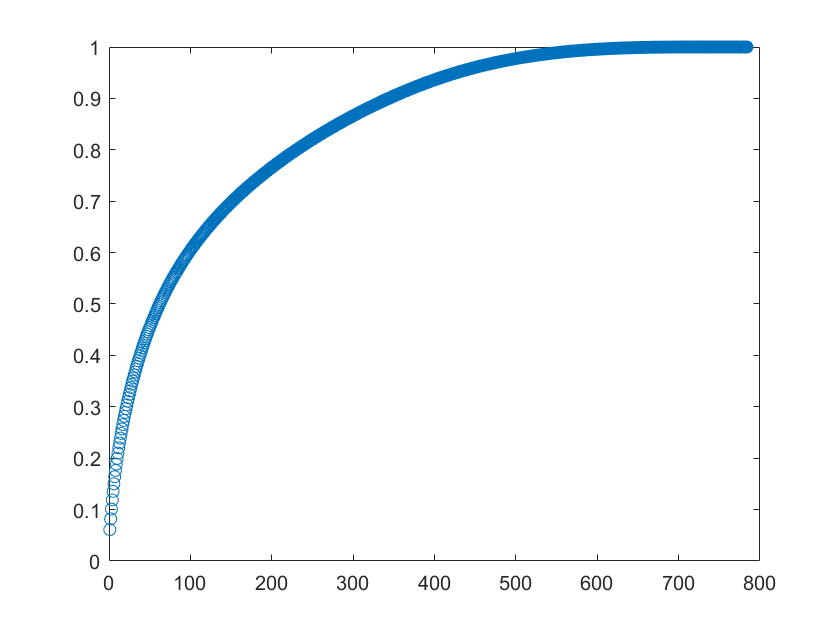

 for i=1:784
 summ = summ + d(i);
 dsum(i) = summ;
 end
 plot(t,dsum/summ,'o')